## Задание 1. Непрерывное и дискретное преобразование Фурье

### ***Использование DFT, Приближение непрерывного с помощью DFT***

Рассмотрим прямоугольную функцию $\prod :\mathbb{R}\to \mathbb{R}:$


$$\prod \left(t\right)=\left\lbrace \begin{array}{ll}
1, & |t|\le \frac{1}{2}\\
0, & |t|>\frac{1}{2}
\end{array}\right.$$


Создаём вектора частот и времени для работы с преобразованием Фурье...

T = 2000; counter = 1;
dt = 0.1;
t=-T/2:dt:T/2;
V = 1/dt; % Ширина диапазона частот
dv = 1/T; % Шаг частоты 
v = -V/2 : dv : V/2; % Набор частот для FFT

**График прямоугольной функции**

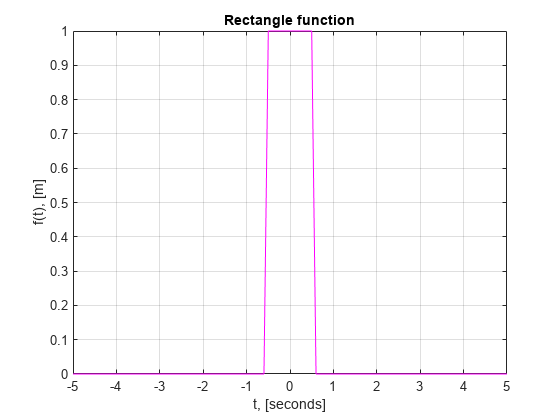

% figure( randi([1 3000],1,1) );
figure;
plot(t, rectangle(t), 'magenta');
grid on
xlabel('t, [seconds]');
xlim([-5, 5])
title("Rectangle function")
ylabel('f(t), [m]');
hold off;

**График образа Фурье прямоугольной функции**

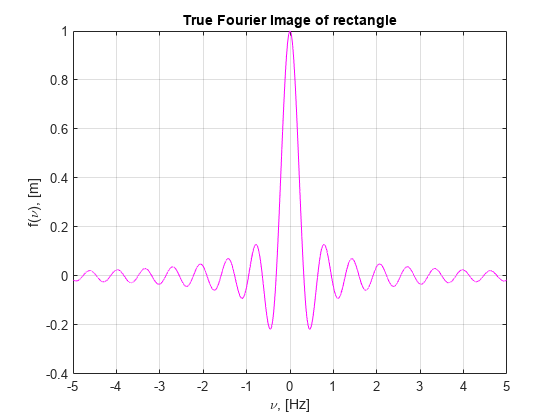

figure;
plot(v, sinc(pi*v), 'magenta');
grid on
xlabel('\nu, [Hz]');
title("True Fourier Image of rectangle")
ylabel('f(\nu), [m]');
hold off;

Теперь будем искать Фурье-образ с помощью классической связки $\textrm{fftshift}\left(\textrm{fft}\left(\right)\right)$

T = 30;
dt = 0.1;
t=-T/2:dt:T/2; 
NN = size(t); N = NN(end);
V = 1/dt; 
dv = 1/T; 
v = -V/2 : dv : V/2; 

Ребята в интернете [говорят](https://www.mathworks.com/matlabcentral/answers/131053-fft-normalization-and-parseval), что вот так его можно нормализовать(унитарным получается сделать)

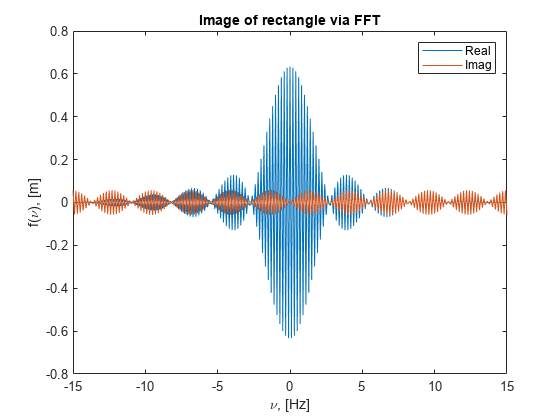

Y = fftshift(fft( rectangle(t) )) / sqrt(N);

figure;
plot(t, real(Y));
hold on
plot(t, imag(Y));
title("Image of rectangle via FFT")
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
legend('Real','Imag')

counter = 17;
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

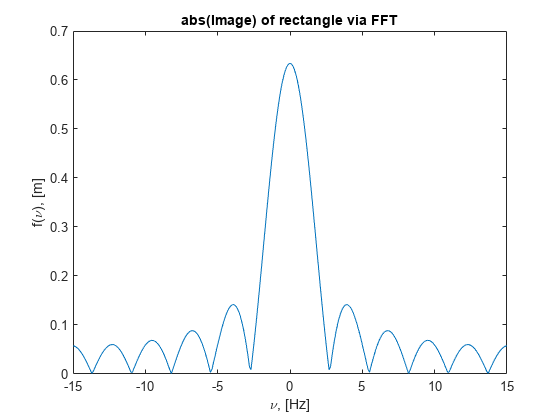


figure;
plot(t, abs(Y));
title("abs(Image) of rectangle via FFT")
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Теперь обратное преобразование:

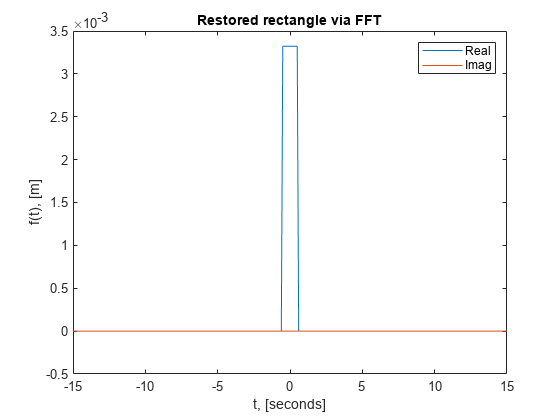

YY = ifft(ifftshift(Y)) / sqrt(N);

figure;
plot(t, real(YY));
hold on
plot(t, imag(YY));
title("Restored rectangle via FFT")
xlabel('t, [seconds]');
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

***Приближение непрерывного с помощью DFT***

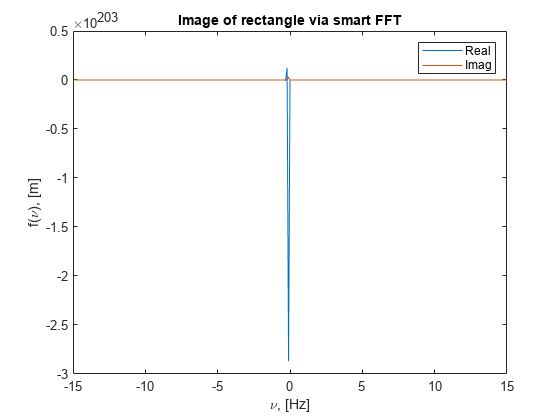

delta_t = t(2) - t(1);
M = fft( rectangle(t) );
Y =   fftshift( delta_t * exp(-2*pi*v*t(1)).* M) / sqrt(N);
figure;
plot(t, real(Y));
hold on
plot(t, imag(Y));
title("Image of rectangle via smart FFT")
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
legend('Real','Imag')



counter = 15;
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;


% figure;
% plot(t, abs(Y));
% title("abs(Image) of rectangle via smart FFT")
% xlabel('\nu, [Hz]');
% ylabel('f(\nu), [m]');

**Теперь обратное преобразование:**

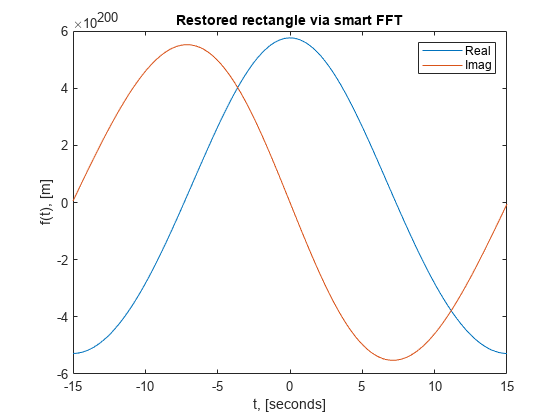

delta_v = v(2) - v(1);
YY = delta_v * ifft(ifftshift(Y)) * sqrt(N);

figure;
plot(t, real(YY));
hold on
plot(t, imag(YY));
title("Restored rectangle via smart FFT")
xlabel('t, [seconds]');
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

## Все функции, используемые в скрипте

**Прямоугольная функция - задание 1**

function y = rectangle(t)
      V0 = 1/2;
      y = ones(size(t));
      y((t > V0)&(t >= 0)) = 0;
      y((t < -V0)&(t <= 0)) = 0;

end